# Fundamentals of GPS - Homework 3

### Tanner Koza

## Problem 1

This problem is to look at noise models.

### Find: 

- **Part A: **Show that the error from the sum **OR** difference of two independent random measurements created from $y=3a\pm4b$, where $a$ and $b$ are both zero mean with variance $\sigma_{a}^2$ and $\sigma_{b}^2$ results in:


$$\sigma_y = \sqrt{9\sigma_{a}^2 + 16\sigma_{b}^2}$$


            Perform 1000 run monte-carlo simulation to verify results.

- **Part B: **Perform a 1000 run monte-carlo simulation (of 10 minutes) to look at the error growth of a random walk (integrated white noise). Use a white noise with 1-sigma value of 0.1 and 0.01 and compare the results. Plot the mean and standard deviation of the monte-carlo simulation along with one run of the simulation (show that the random walk is zero mean with a standard deviation is $\sigma_{\int w} = \sigma_w\Delta t\sqrt{k} = \sigma_w\sqrt{t\times\Delta t}$ (where $k$ is sample number).

- **Part C: **Perform a 1000 monte-carlo simulation to look at the error growth of a 1st order markov process (integrated filtered noise) of the form $\dot{x}=-\frac{1}{\tau} x+1$. Use the same noise characteristics as above and compare the results with a 1 second and 100 second time constant (this results in 4 combinations). Comment on how changing the time constant and changing the standard deviation of the noise effects the error. Show that the 1st order markov process is zero mean with a standard deviation of is $\sigma_x = \sigma_w \Delta t \sqrt{(\frac{A^{2t}-1}{A^2-1})}$ where $A=(1-\frac{\Delta t}{\tau})$. Note that for a positive time constant (i.e. stable system) the standard deviation has a steady state value.

### Solution: 

- **Part A: **The following code runs a monte-carlo

numMeas = 1;
numSims = 1000;

var_a = 10;
var_b = 25;

sigma_a = sqrt(var_a);
sigma_b = sqrt(var_b);
sigma_y = sqrt( (9 * var_a) + (16 * var_b) );

ysum = zeros(numSims, 1); % preallocation
ydiff = zeros(numSims, 1);

for j = 1:numSims
    a = sigma_a * randn(numMeas, 1);
    b = sigma_b * randn(numMeas, 1);
    
    ysum(j) = ( 3 .* a ) + ( 4 .* b );

    ydiff(j) = ( 3 .* a ) - ( 4 .* b );
end

mean_ysum = mean(ysum);
mean_ydiff = mean(ydiff);

sigma_ysum = std(ysum);
sigma_ydiff = std(ydiff);

clearvars

- **Part B: **

- **Part C:**

## **Problem 2**

### Find:

- Determine the expected uncertainty for an L1-L5 ionosphere free pseudorange measurement and L2-L5 ionosphere free pseudorange. Assuming all measurements have the same accuracy (L1, L2, L5) which will provide the best ionosphere estimate?

### Solution:

- s

## Problem 3

### Find:

- Show that the differential GPS problem is linear. In other words derive the following expression:


$$\Delta \rho = \left[ \matrix{uv_x & uv_y & uv_z & 1}\right]
\left[ \matrix{r_x \cr r_y \cr r_z \cr c \delta t_{ab}}\right]$$


### Solution:

- s

## Problem 4

Set up your own 2D planar trilateration problem. Place the SVs at (0,300) (100,400), (700,400), and (800,300). Generate a range measurement for a base station at (400,0) and a user at (401,0).

### Find:

- **Part A: **Solve for the position of the user using 2 SVs and then 4 SVs assuming no clock errors. How does the PDOP change for the two cases?

- **Part B: **Solve for the position of the user assuming you need to solve for the user clock bias. What is the PDOP with all 4 satellites.

- **Part C: **Calculate a differential solution between the base and user using a single difference model and assuming you must solve for a clock bias between the base station and user. What is the PDOP with all 4 satellites?

- **Part D: **Calculate a differential solution between the base and user using a double difference model to remove the clock bias between the base station and user. What is the PDOP with all 4 satellites?

- **Part E: **Assuming the range error is zero mean with unit variance, what is the order of accuracy in the above 4 solution methods?

### Solution:

- **Part A:**

- **Part B:**

- **Part C:**

- **Part D:**

- **Part E:**

## **Problem 5**

### **Find:**

- (Bonus for Undergrads/Required for Grads). Repeat problem #3 using 4 and 8 SV positions from Lab #2 (4,7,8,9,16,21,27,30). Comment on any difference or similarities with the planar problem in #3.

### Solution:

- s

## Problem 6

Chapter 2, Problem 1a and 1b for PRN #4. Repeat 1a for PRN #7.

### Find:

- **Part A: **Create the entitr 1023-chip C/A code for the PRNs as a vector. Plot the first 16 and last 16 chips in the code.

- **Part B: **Create the C/A code output from time epochs 1024 to 2046. How does this compare to Part A?

### Solution:

- **Part A: **The function used to calculate the C/A code for PRN 4 and 7 was validated by checking if the hex representation of the first 16 chips of PRN 19 was E6D6. Although it is not shown here, they did match indicating the other PRNs are also correct. The plots for the first and last 16 chips of each PRN are shown below.

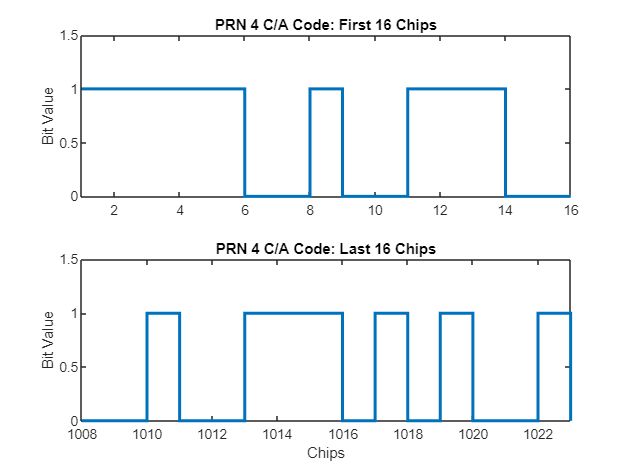

codeL = 1023;

CA4 = genCA(4, codeL);
CA7 = genCA(7, codeL);

chips = 16;

first = 1:chips;
last = codeL-(chips-1):codeL;

figure
subplot(2,1,1)
stairs(first, CA4(first), 'LineWidth', 2)
xlim([first(1) first(end)])
ylim([0 1.5])
title('PRN 4 C/A Code: First 16 Chips')
ylabel('Bit Value')

subplot(2,1,2)
stairs(last, CA4(last), 'LineWidth', 2)
xlim([last(1) last(end)])
ylim([0 1.5])
title('PRN 4 C/A Code: Last 16 Chips')
xlabel('Chips')
ylabel('Bit Value')

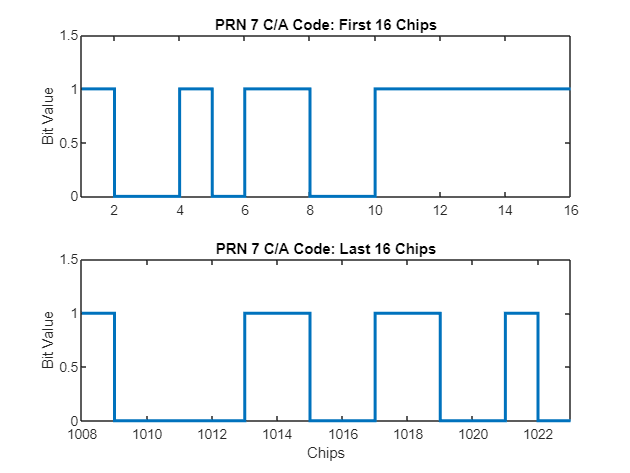


figure
subplot(2,1,1)
stairs(first, CA7(first), 'LineWidth', 2)
xlim([first(1) first(end)])
ylim([0 1.5])
title('PRN 7 C/A Code: First 16 Chips')
ylabel('Bit Value')

subplot(2,1,2)
stairs(last, CA7(last), 'LineWidth', 2)
xlim([last(1) last(end)])
ylim([0 1.5])
title('PRN 7 C/A Code: Last 16 Chips')
xlabel('Chips')
ylabel('Bit Value')


clearvars

- **Part B: **The following plots for time epochs (total chips from start of code generation) 1024 to 2046 are shown below. The exactly replicate those shown in PArt A meaning the code repeates every 1023 epochs or chips.

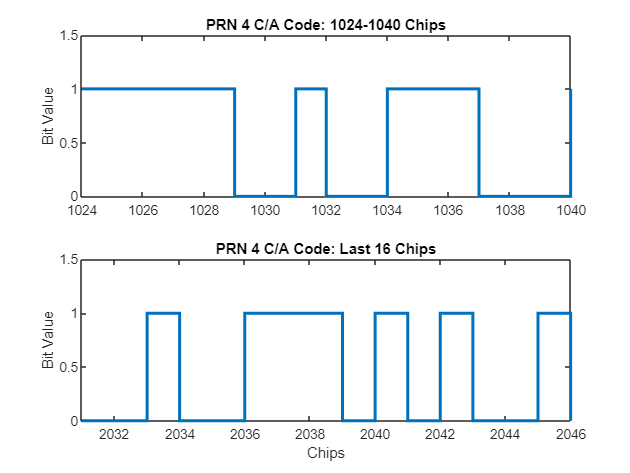

codeL = 2046;

CA4 = genCA(4, codeL);
CA7 = genCA(7, codeL);

chips = 16;

first = 1024:1040;
last = codeL-(chips-1):codeL;

figure
subplot(2,1,1)
stairs(first, CA4(first), 'LineWidth', 2)
xlim([first(1) first(end)])
ylim([0 1.5])
title('PRN 4 C/A Code: 1024-1040 Chips')
ylabel('Bit Value')

subplot(2,1,2)
stairs(last, CA4(last), 'LineWidth', 2)
xlim([last(1) last(end)])
ylim([0 1.5])
title('PRN 4 C/A Code: Last 16 Chips')
xlabel('Chips')
ylabel('Bit Value')

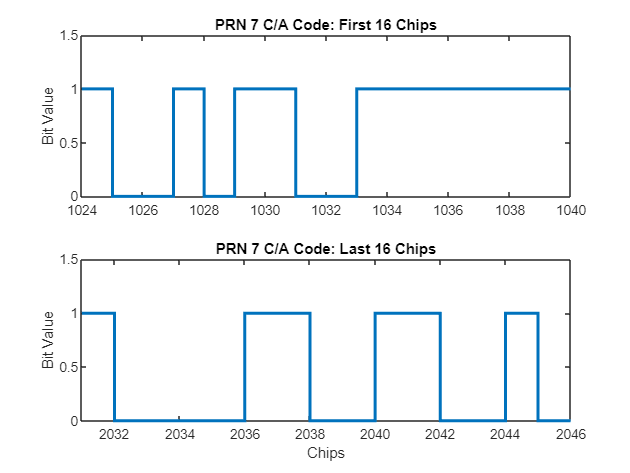


figure
subplot(2,1,1)
stairs(first, CA7(first), 'LineWidth', 2)
xlim([first(1) first(end)])
ylim([0 1.5])
title('PRN 7 C/A Code: First 16 Chips')
ylabel('Bit Value')

subplot(2,1,2)
stairs(last, CA7(last), 'LineWidth', 2)
xlim([last(1) last(end)])
ylim([0 1.5])
title('PRN 7 C/A Code: Last 16 Chips')
xlabel('Chips')
ylabel('Bit Value')


clearvars

## Problem 7

Using your PRN sequence for PRN 4 and 7, repeat problem #2 from HW#1. Compare the results to the results for your made up sequence.

### Find:

- **Part A: **Plot the histogram on each sequence.

- **Part B: **Plot the spectral analysis on each sequence.

- **Part C: **Plot the autocorrelation each sequence with itself (i.e. a sequence delay cross correlation).

- **Part D: **Plot the cross autocorrelation between the two sequences.

### Solution:

- **Part A: **The following plots show the histograms of PRN 4 and 7 for a code length of 1023 chips. The 0 chips were converted to -1 values to be used in Problem 8. The results are essentially identical to the made up sequence from HW1. This demonstrates the C/A code posseses the same qualities as a completely random sequence.

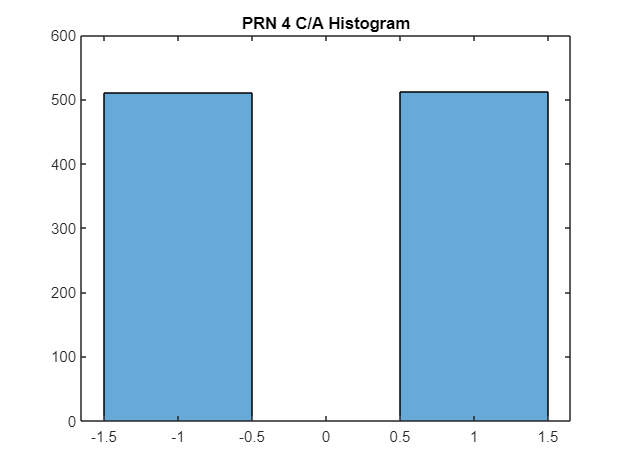

codeL = 1023;

CA4 = genCA(4, codeL);
CA7 = genCA(7, codeL);

idx4 = CA4 == 0;
idx7 = CA7 == 0;

CA4(idx4) = -1;
CA7(idx7) = -1;

figure
histogram(CA4)
title('PRN 4 C/A Histogram')

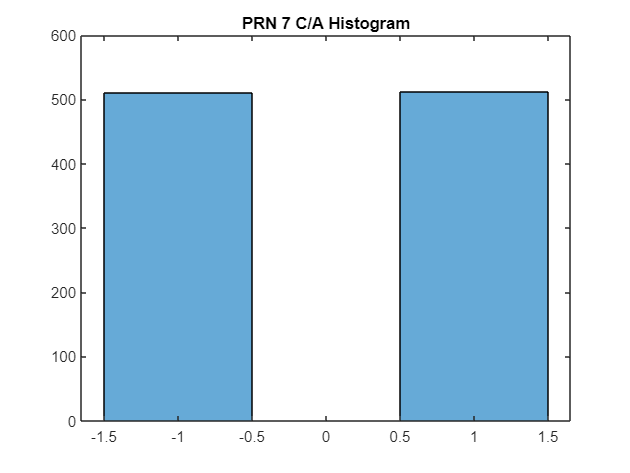

figure
histogram(CA7)
title('PRN 7 C/A Histogram')

- **Part B: **The following plots show the Power Spectral Density for PRN 4 and 7. Once again, they look essentially identical to the PSDs from the sequences generated in HW1. This further solidifies the claim that the PRN C/A code behaves the same way as a completely random sequence. 

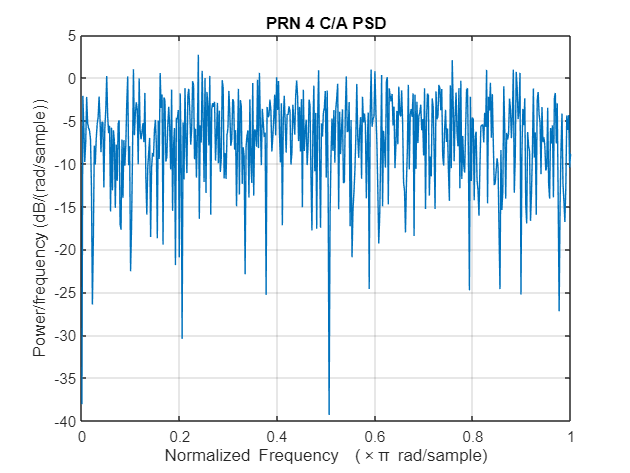

figure
periodogram(CA4)
title('PRN 4 C/A PSD')

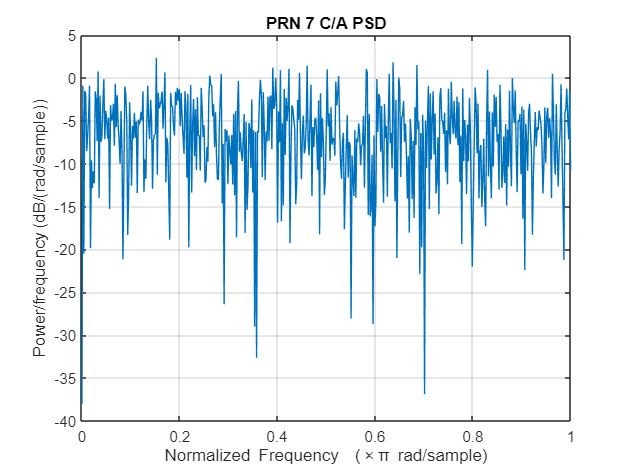

figure
periodogram(CA7)
title('PRN 7 C/A PSD')

- **Part C: **The following plots show the autocorrelation for PRN 4 and 7. Like before, they look the same as the sequences generated in HW1. They are only correlated with themselves at one point in time (when aligned) which means they possess the same qualities as a random sequence.

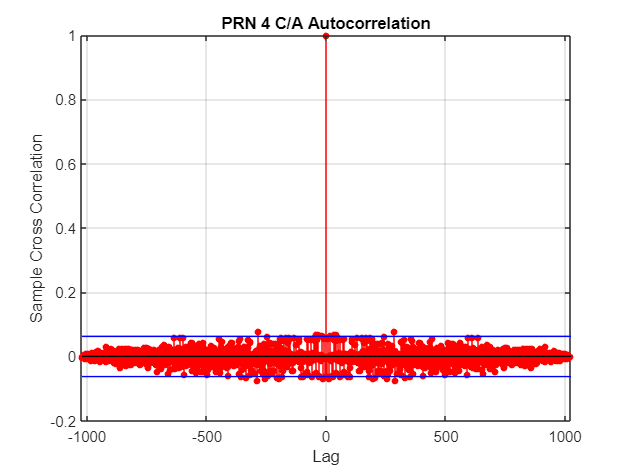

figure
crosscorr(CA4, CA4, 'NumLags', codeL-1)
title('PRN 4 C/A Autocorrelation')
xlim([-codeL codeL])

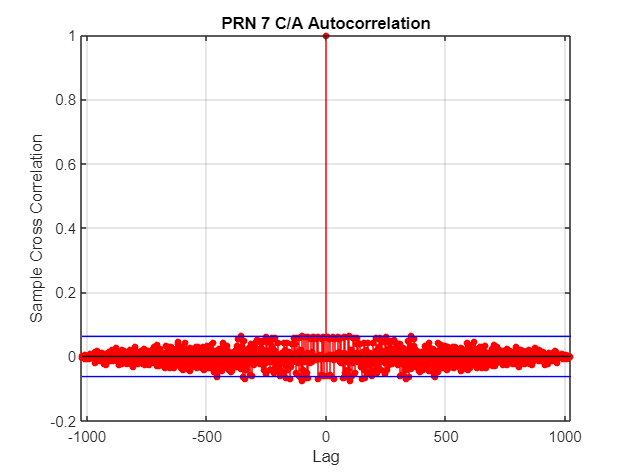

figure
crosscorr(CA7, CA7,  'NumLags', codeL-1)
title('PRN 7 C/A Autocorrelation')
xlim([-codeL codeL])

- **Part D: **The following plot shows the cross correlation for PRN 4 and 7. As in HW1, there is no definite correlation at any point shifted in time meaning the two are always distinguishable. Once again, another property of random sequences.

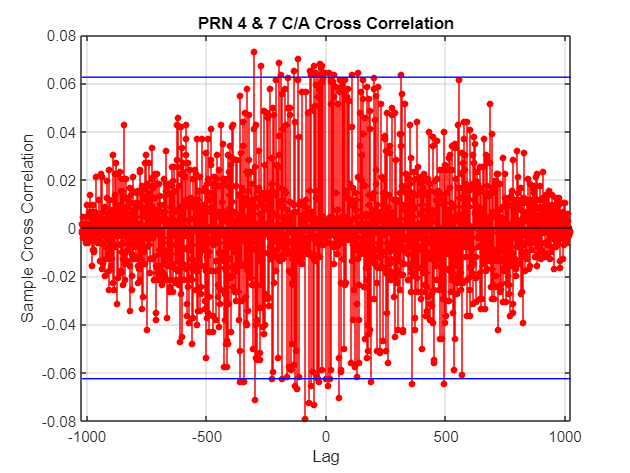

figure
crosscorr(CA4, CA7, 'NumLags', codeL-1)
title('PRN 4 & 7 C/A Cross Correlation')
xlim([-codeL codeL])

## **Problem 8**

### **Find:**

- Take your C/A code from problem above (i.e. PRN #4 and #7) and multiply it times the L1 Carrier (your C/A code must be in the form -1 and +1). Perform a spectral analysis (magnitude) on the resultant signal. You will need to make sure to “hold” your C/A code bits for the correct length of time (I suggest using a sample rate 10x the L1 carrier frequency – meaning each chip of the C/A code will be used for 10 samples of the sine wave).

### Solution:

- The following plots show the PSD of the resultant signals.

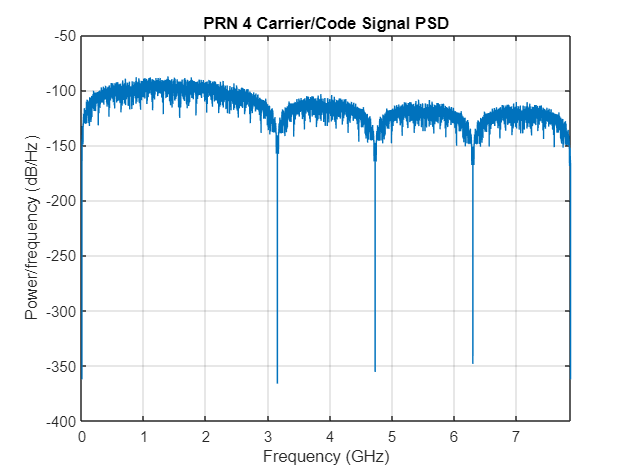

codeL = 1023;

CA4 = genCA(4, codeL);
CA7 = genCA(7, codeL);

idx4 = find(CA4 == 0);
idx7 = find(CA7 == 0);

CA4(idx4) = -1;
CA7(idx7) = -1;

CA4 = reshape(repmat(CA4',10,1),1,[]);
CA7 = reshape(repmat(CA7',10,1),1,[]);

fL1 = 1575.42e6; % L1 frequency (Hz)

fs = fL1*10;

dt = 1/fs;

t = 0:dt:dt*(length(CA4)-1);

L1car = sin((fL1*2*pi).*t);

L1sig4 = L1car .* CA4;

L1sig7 = L1car .* CA7;

figure
periodogram(L1sig4,[],length(L1sig4),fs)
title('PRN 4 Carrier/Code Signal PSD')

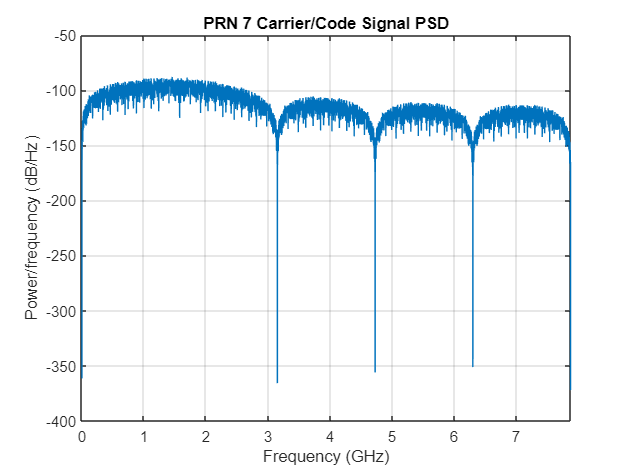

figure
periodogram(L1sig7,[],length(L1sig7),fs)
title('PRN 7 Carrier/Code Signal PSD')